Question 1:

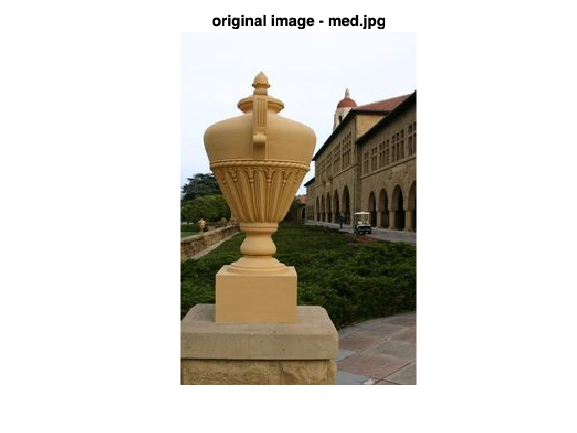

I = imread('HW3_images/med.jpg');
figure;
imshow(I);
title('original image - med.jpg')

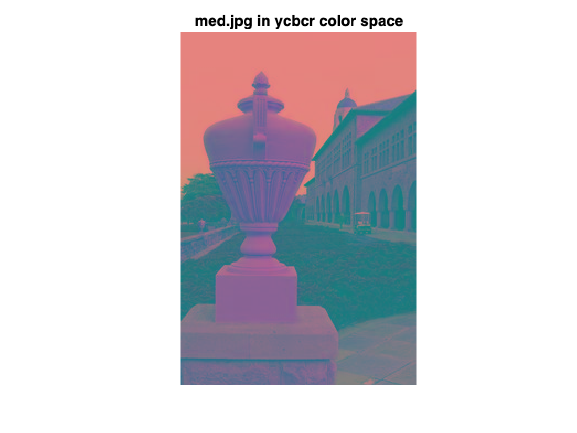

% image in ycbcr color space
Iycbcr = rgb2ycbcr(I);
figure;
imshow(Iycbcr);
title('med.jpg in ycbcr color space');

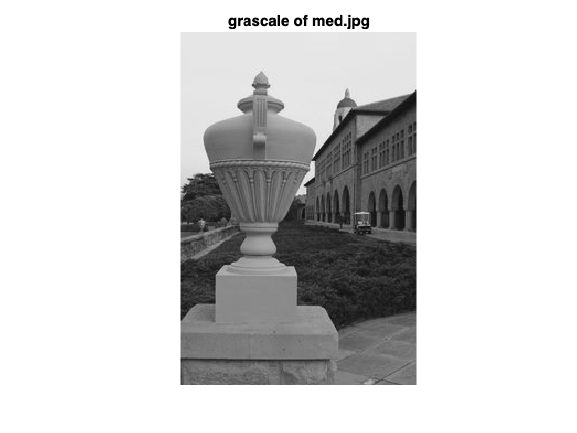

% grayscale image
Igray = Iycbcr(:,:,1);
figure;
imshow(Igray);
title('grascale of med.jpg')

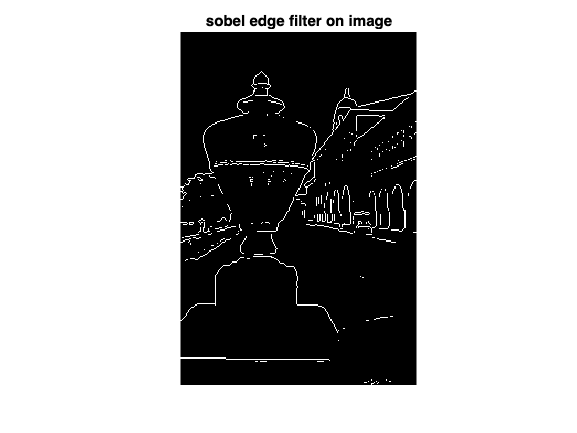

% result of sobel edge filter
Isobel = edge(Igray, "sobel");
figure;
imshow(Isobel, []);
title('sobel edge filter on image');

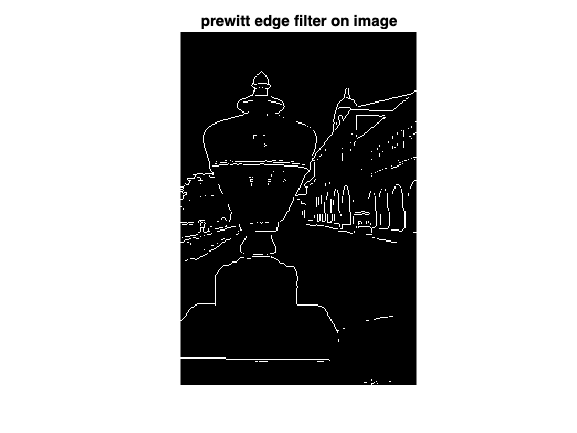

% result of prewitt edge filter
Iprewitt = edge(Igray, "prewitt");
figure;
imshow(Iprewitt);
title('prewitt edge filter on image');

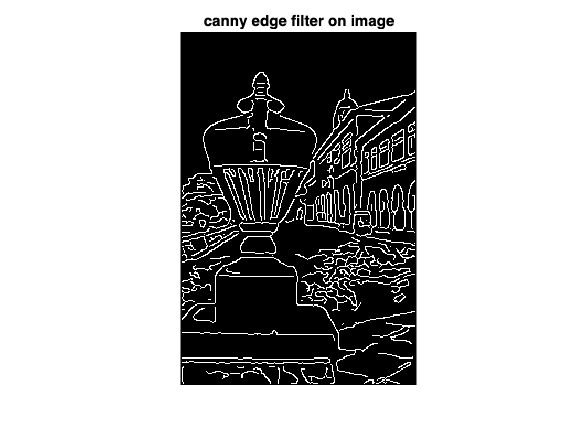

% result of canny edge filter
Icanny = edge(Igray, "canny");
figure;
imshow(Icanny);
title('canny edge filter on image');

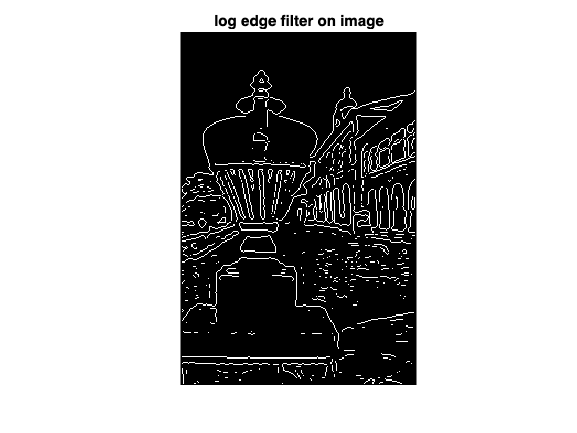

% result of log edge filter
Ilog = edge(Igray, "log");
figure;
imshow(Ilog);
title('log edge filter on image');

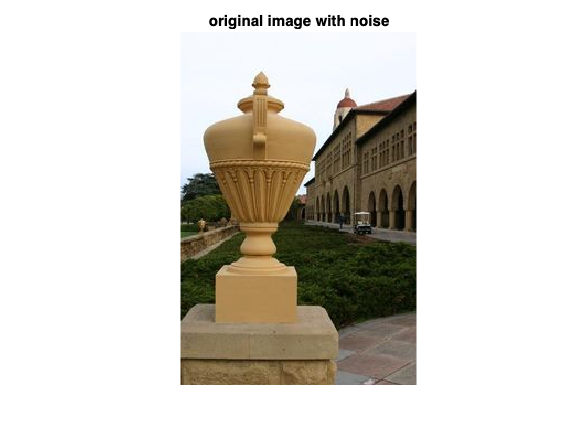

% original image with added noise
figure;
Inoise = imnoise(I);
imshow(I);
title('original image with noise')

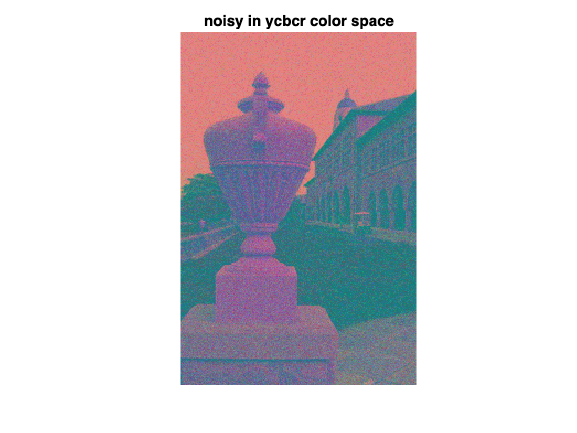

% image in ycbcr color space
Iycbcr = rgb2ycbcr(Inoise);
figure;
imshow(Iycbcr);
title('noisy in ycbcr color space');

Image filtered using the Sobel filter seems to identify edges when there is a significant color shift across the edges (e.g. edges separating the sculpture in the front from the grass).The Sobel filter creates an image which emphasizes edges and transitions. It is a discrete differentiation operator that computes an approximation of the gradient of the image intensity function. At each point in the image, the result of the Sobel operator is either the corresponding gradient vector or the norm of this vector. The Sobel operator is based on convolving the image with a small, separable, and integer valued filter in the horizontal and vertical directions. The gradient approximation that the Sobel filter produces is often relatively crude, in particular for high frequency variations in the image.

The Prewitt filter only identifies edges that are horizontal or vertical using the Prewitt transform and ignored all the other edges.

The Canny filter seems to work best in this case. The Canny filter is a multi-stage edge detector. It uses a filter based on the derivative of a Gaussian in order to compute the intensity of the gradients. The Gaussian reduces the effect of noise present in the image. Then, potential edges are thinned down to 1-pixel curves by removing non-maximum pixels of the gradient magnitude. Finally, edge pixels are kept or removed using hysteresis thresholding on the gradient magnitude.

Log filter also does a good job at detecting the edges in the image. Log filter finds edges by looking for zero-crossings after filtering `I` with a Laplacian of Gaussian (LoG) filter.

Applying the same filters on the same image after apply a layer of noise, it appears that the result from Prewitt and Sobel fitler are more or less similar to the result of applying it on the noise free image. This could be because the approximation performed by Sobel is crude and not impacted by the noise too much, which in case of Prewitt, the noise introducted was uniform and didn't have any horizontal or vertical line characteristics. Canny filter seems to have picked up a lot more of the weak edges after adding the noise as addition of noise seems to have linked more weak edges with the strong ones. Log filter seems to do the best job of all the required edges while also having some unwanted smaller ones.

Question 2:

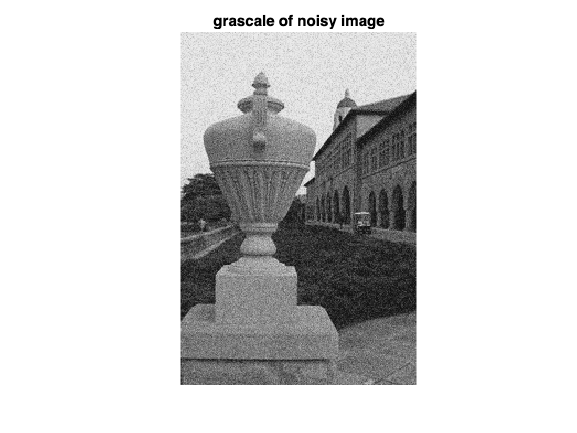

% grayscale image
Igray = Iycbcr(:,:,1);
figure;
imshow(Igray);
title('grascale of noisy image');

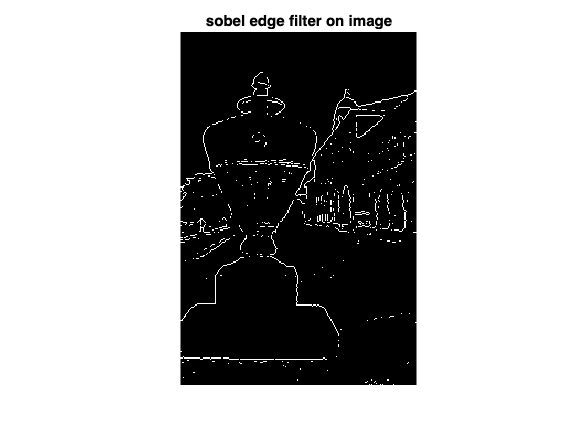

Isobel = edge(Igray, "sobel");
figure;
imshow(Isobel, []);
title('sobel edge filter on image');

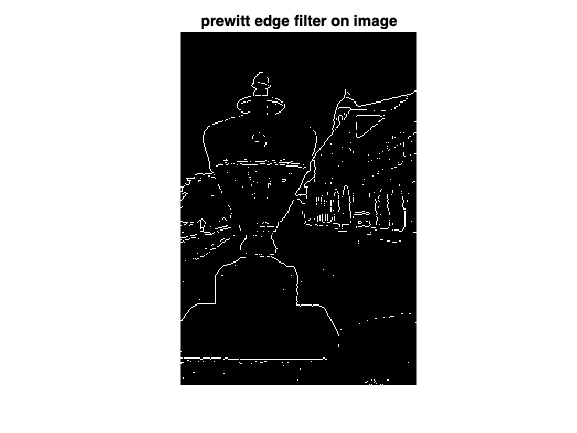

% result of prewitt edge filter
Iprewitt = edge(Igray, "prewitt");
figure;
imshow(Iprewitt);
title('prewitt edge filter on image');

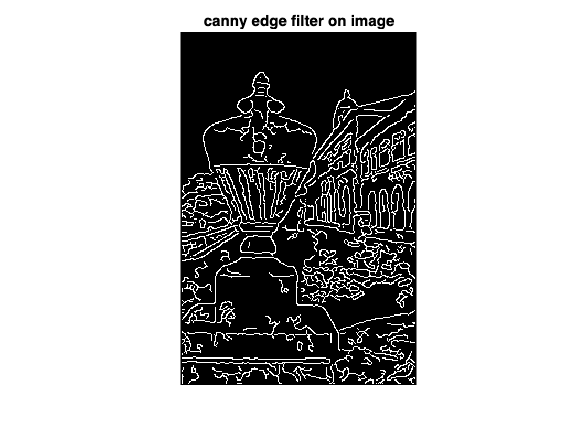

% result of canny edge filter
Icanny = edge(Igray, "canny");
figure;
imshow(Icanny);
title('canny edge filter on image');

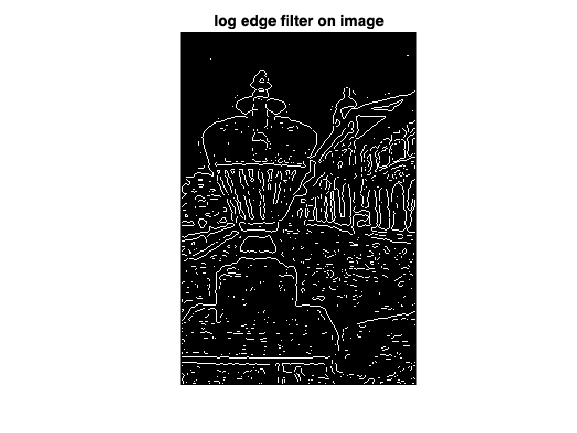

% result of log edge filter
Ilog = edge(Igray, "log");
figure;
imshow(Ilog);
title('log edge filter on image');

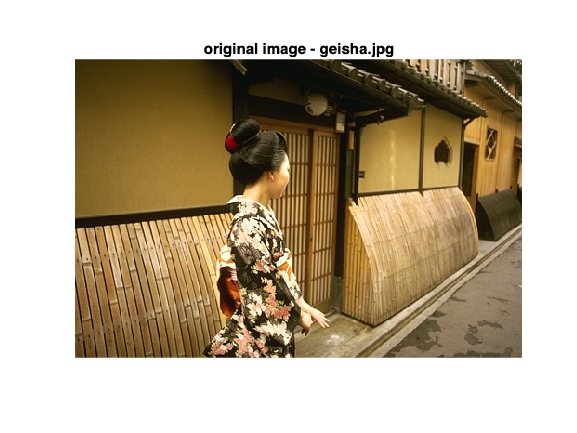

I = imread('HW3_images/geisha.jpg');
figure;
imshow(I);
title('original image - geisha.jpg')

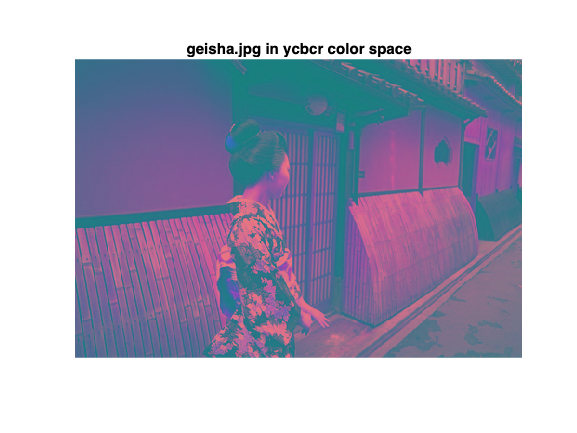

% image in ycbcr color space
Iycbcr = rgb2ycbcr(I);
figure;
imshow(Iycbcr);
title('geisha.jpg in ycbcr color space');

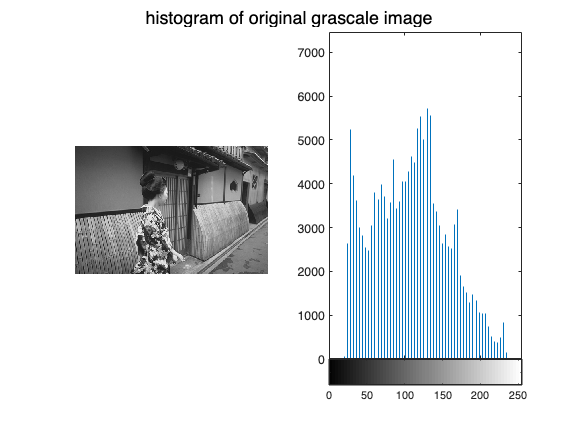

% grayscale image
Igray = Iycbcr(:,:,1);
figure;
subplot(1,2,1);
imshow(Igray);
subplot(1,2,2);
imhist(Igray,64);
sgtitle('histogram of original grascale image');

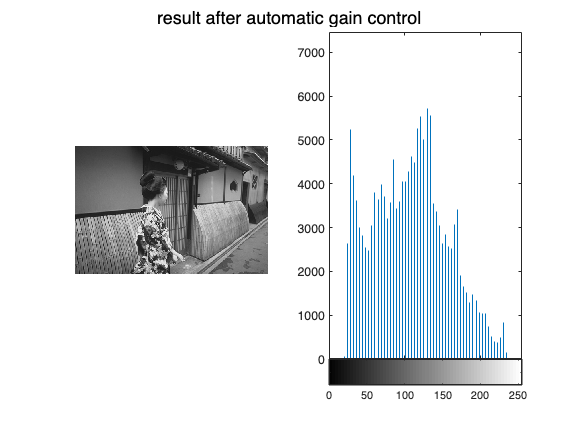

% automatic gain control
A = min(Igray, [], 'all');
B = max(Igray, [], 'all');
K = 256;
alpha = (K - 1) / (B - A);
beta = -A * alpha;
Iacg = alpha * Igray + beta;
figure;
subplot(1,2,1);
imshow(Iacg);
subplot(1,2,2);
imhist(Iacg,64);
sgtitle('result after automatic gain control');

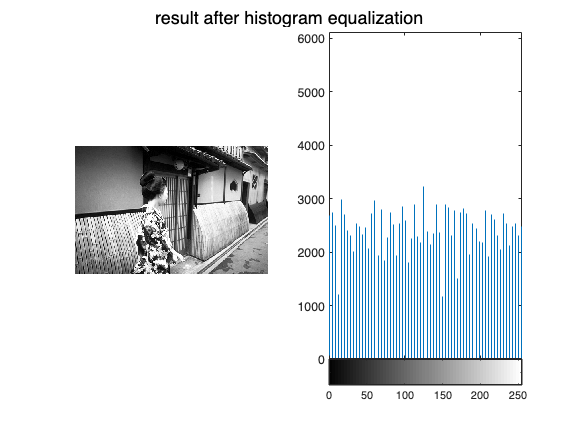

% histogram equalization
Ihe = histeq(Igray);
figure;
subplot(1,2,1);
imshow(Ihe);
subplot(1,2,2);
imhist(Ihe,64);
sgtitle('result after histogram equalization');

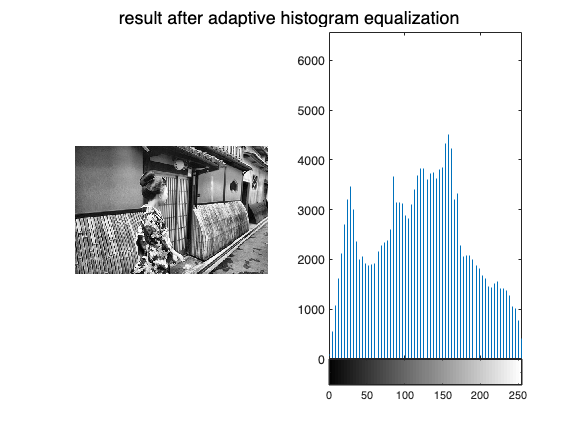

% adaptive histogram equalization
Iahe = adapthisteq(Igray);
figure;
subplot(1,2,1);
imshow(Iahe);
subplot(1,2,2);
imhist(Iahe,64);
sgtitle('result after adaptive histogram equalization');

Automatic gain control process seems to increase the dynamic range of the image without any loss of details especially in the shadows. While historgram equalization process seems to take things to the extreme, blowing up the bright spots and darkening the shadows causing loss of detail. Adaptive histogram equalization seems to do a good job of increasing the contrast while retaining the relative brightness of objects in the image. 

Question 3:

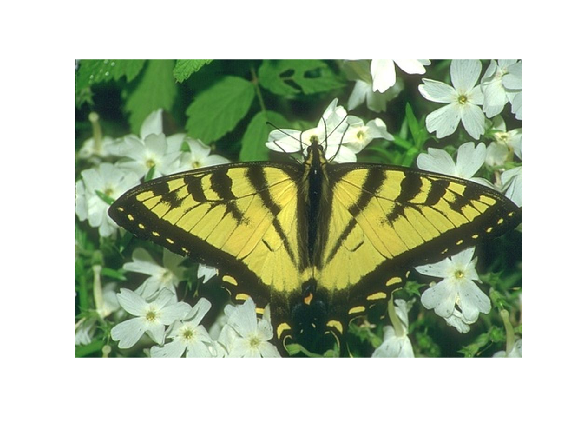

I = imread('HW3_images/butterfly.jpg');
figure;
imshow(I)

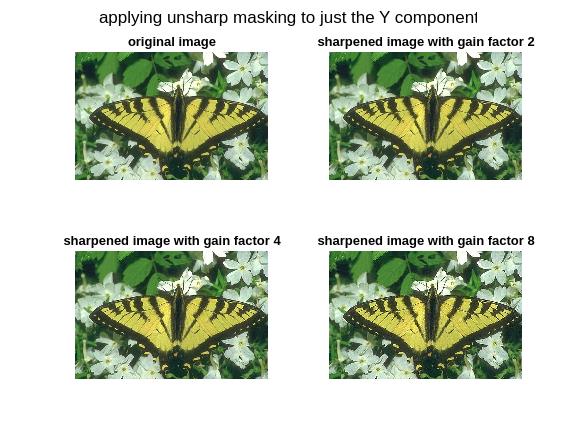


Iycbcr = rgb2ycbcr(I);
Igray = double(Iycbcr(:,:,1));
kernel = fspecial('gaussian',5);

% apply gaussian filter on the image
Ismooth_gray = imfilter(Igray, kernel);

% apply unsharp masking filter on the image
Is_beta2 = Ismooth_gray + 2 * (Igray - Ismooth_gray);
Is_beta4 = Ismooth_gray + 4 * (Igray - Ismooth_gray);
Is_beta8 = Ismooth_gray + 8 * (Igray - Ismooth_gray);

Iycbcr_beta2 = Iycbcr;
Iycbcr_beta4 = Iycbcr;
Iycbcr_beta8 = Iycbcr;

Iycbcr_beta2(:,:,1) = Is_beta2;
Iycbcr_beta4(:,:,1) = Is_beta4;
Iycbcr_beta8(:,:,1) = Is_beta8;

figure;
subplot(2,2,1);
imshow(I);
title('original image', FontSize=10);
subplot(2,2,2);
imshow(ycbcr2rgb(Iycbcr_beta2));
title('sharpened image with gain factor 2', FontSize=10);
subplot(2,2,3);
imshow(ycbcr2rgb(Iycbcr_beta4));
title('sharpened image with gain factor 4', FontSize=10);
subplot(2,2,4);
imshow(ycbcr2rgb(Iycbcr_beta8));
title('sharpened image with gain factor 8', FontSize=10);
sgtitle('applying unsharp masking to just the Y component');

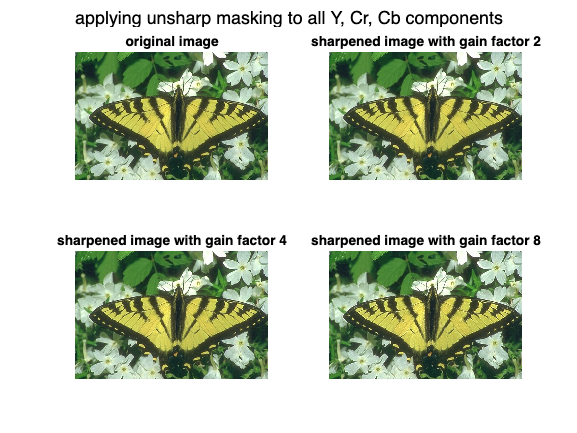

Iycbcr = rgb2ycbcr(I);
kernel = fspecial('gaussian',5);

% apply gaussian filter on the image
Isy = imfilter(Iycbcr(:,:,1), kernel);
Iscb = imfilter(Iycbcr(:,:,2), kernel);
Iscr = imfilter(Iycbcr(:,:,3), kernel);

Ismooth = Iycbcr;
Ismooth(:,:,1) = Isy;
Ismooth(:,:,2) = Iscb;
Ismooth(:,:,3) = Iscr;

% apply unsharp masking filter on the image
Is_beta2 = Ismooth + 2 * (Iycbcr - Ismooth);
Is_beta4 = Ismooth + 4 * (Iycbcr - Ismooth);
Is_beta8 = Ismooth + 8 * (Iycbcr - Ismooth);

figure;
subplot(2,2,1);
imshow(I);
title('original image', FontSize=10);
subplot(2,2,2);
imshow(ycbcr2rgb(Is_beta2));
title('sharpened image with gain factor 2', FontSize=10);
subplot(2,2,3);
imshow(ycbcr2rgb(Is_beta4));
title('sharpened image with gain factor 4', FontSize=10);
subplot(2,2,4);
imshow(ycbcr2rgb(Is_beta8));
title('sharpened image with gain factor 8', FontSize=10);
sgtitle('applying unsharp masking to all Y, Cr, Cb components');

Applying unsharp masking only on the Y (luminance) component of the YCbCr image seems to provide a more natural, better looking image with colors being closer to the original image. This is because applying unsharp masking on the Cb and Cr components tends to distort the color composition of the image especially at the edges, since it over-emphasizes the change in color across the edges.